# Diferenciación Numérica

La diferenciación númerica aproxima el valor de una de la derivada de una función utilizando una serie de puntos, la cual puede ser dada o se pueden obtener de la misma función pasada como parametro.

    En este caso usaremos la segunda opción, es decir, definiremos una función y=f(x)

syms f(x);
f(x)=exp(-x)    %function to proceed

$$f(x) = {\mathrm{e}}^{-x}$$

El método utilizado para aproximar será el de las series de Taylor. Esto tiene como consecuencia que existan dos fuentes de error inevitables:

- redondeo de la maquina (debido a la precisión limitada)

- error de truncamiento de las series de taylor (no planeamos resolverlas hasta converger, sino truncarlas en cierto punto)

## Series de Taylor

Por definición, la aproximación con una serie de taylor par auna función $$f(x)$$ alderedor del punto $$a$$ es:


$$f\left(x\right)\;\approx f\left(a\right)+\frac{f^{\prime } \left(a\right)}{1!}\left(x-a\right)+\frac{f^{\prime \prime } \left(a\right)}{2!}{\left(x-a\right)}^2 +\ldotp \ldotp \ldotp ,=\sum_{n=0}^{\infty } \frac{f^{\left(n\right)} \left(a\right)}{n!}{\left(x-a\right)}^n$$


Ahora, si aproximamos en funcion de $x+h$ alrededor de un punto $x$


$$f\left(x+h\right)\approx f\left(x\right)+\frac{f^{\prime } \left(x\right)}{1!}\left(h\right)+\frac{f^{\prime \prime } \left(x\right)}{2!}{\left(h\right)}^2 +\ldotp \ldotp \ldotp ,=\sum_{n=0}^{\infty } \frac{f^{\left(n\right)} \left(x\right)}{n!}{\left(h\right)}^n$$


## Primera derivada

Resolviendo varias funciones de taylor, podemos despejar la primera derivada de x de la ecuacion resultante al substraer de la serie de f(x+h) alrededor de x de la serie de f(x-h) alrededor de x.


$$f\left(x+h\right)-f\left(x-h\right)\approx 2\left\lbrack {\textrm{hf}}^{\prime } \left(x\right)+\frac{h^3 }{3!}f^{\prime \prime \prime } \left(x\right)+\ldotp \ldotp \ldotp ,\right\rbrack$$


despejando para ${f}'(x)$


$$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}-\frac{1}{h}\left(\frac{h^3 }{3!}{{f^{\prime } }^{\prime } }^{\prime } \left(x\right)+\ldotp \ldotp \ldotp ,\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}-\frac{h^2 }{6}{{f^{\prime } }^{\prime } }^{\prime } \left(x\right)-\ldotp \ldotp \ldotp$$


por lo que si fijamos x y variamos h para identificar la precision de la aproximación, podemos asumir que el error de truncamiento se comporta como $h^2$. Es decir,

$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$$$+ \mathcal{O}(h^2)$$.

Ya que *h *es la mayoria de las veces menor a 1, a mayor grado de exponente en *h*, mejor es la aproximación.

En el caso de querer mejorar la precisión, deberiamos calcular más series de Taylor como funciones de $x\pm (n)h$ y cancelaras entre sí.

## Generalización

Usando el método anteriormente descrito, llegamos a tres formas distintas, las aproximaciones centradas, hacia adelante y hacia atrás. Analizaremos la primera y la segunda derivada de las funciones $f(x) = e^{-x}$  y $g(x) = \ln{x}$

format long
func1 = matlabFunction(f(x));
c=0.6;                              % h expansion factor
lim = 50;
i = 1:lim;                          % number of h -> hs = [h^1,..,h^i,...h^lim]
arr = @(x) double(power(c,x));
hs = arr(i);
x=2                                 % x to calculate the derivative on

x =      2


## Diferencia Central Finita

Las aproximaciones pueden realizarse de forma "centralizada", este nombre proviene de la necesidad de calcular los puntos $f\left(x+h\right)$ y $f\left(x-h\right)$ para una x que se encuentra en el centro de estos dos. 

    Usaremos las dos siguientes formulas para aproximar la primera y segunda derivada de las funciones.


$$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$$

$$$+ \mathcal{O}(h^2)$$$



$$f^{\prime \prime } \left(x\right)\approx \frac{f\left(x+h\right)-2f\left(x\right)+f\left(x-h\right)}{h^2 }$$

$$$+ \mathcal{O}(h^2)$$$


%calcular valor real
df      = diff(f)              %Primer derivada 

$$df(x) = -{\mathrm{e}}^{-x}$$

df_x    = double(df(x))        % real value of df/dx (x)

df_x =   -0.135335283236613


d2f     = diff(f,2)            %Segunda derivada

$$d2f(x) = {\mathrm{e}}^{-x}$$

df2_x   = double(d2f(x))       % real value of d^2f/dx^2 (x)

df2_x =    0.135335283236613


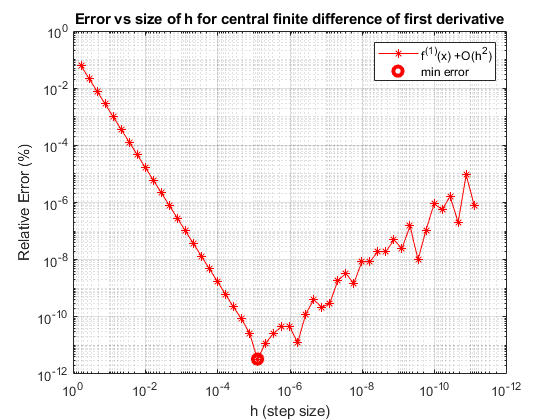


error           = zeros([10,length(hs)]);
approximations  = zeros([1,10]);

j=1;
for h = hs
    approximations(1) = firstCenteredDerivative(func1,x,h);     %centered first derivative - h^2
    approximations(2) = secondCenteredDerivative(func1,x,h);    %centered second derivative - h^2
    approximations(3) = forwardFiniteDifference(func1,x,h,1,1); %forward Finite first derivative -h
    approximations(4) = forwardFiniteDifference(func1,x,h,1,2); %forward Finite first derivative -h^2
    approximations(5) = forwardFiniteDifference(func1,x,h,2,1); %forward Finite second derivative -h
    approximations(6) = forwardFiniteDifference(func1,x,h,2,2); %forward Finite second derivative -h^2
    approximations(7) = backwardFiniteDifference(func1,x,h,1,1);%backward Finite first derivative -h
    approximations(8) = backwardFiniteDifference(func1,x,h,1,2);%backward Finite first derivative -h^2
    approximations(9) = backwardFiniteDifference(func1,x,h,2,1);%backward Finite second derivative -h
    approximations(10)= backwardFiniteDifference(func1,x,h,2,2);%backward Finite second derivative -h^2
    error(1,j)=abs(approximations(1)/df_x -1);
    error(2,j)=abs(approximations(2)/df2_x -1);
    error(3,j)=abs(approximations(3)/df_x -1);
    error(4,j)=abs(approximations(4)/df_x -1);
    error(5,j)=abs(approximations(5)/df2_x -1);
    error(6,j)=abs(approximations(6)/df2_x -1);
    error(7,j)=abs(approximations(7)/df_x -1);
    error(8,j)=abs(approximations(8)/df_x -1);
    error(9,j)=abs(approximations(9)/df2_x -1);
    error(10,j)=abs(approximations(10)/df2_x -1);
    j = j+1;
end


figure;
loglog(hs,error(1,:),'r-*')
hold on
[minV,idx] = min(error(1,:));
loglog(hs(idx),error(1,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
xlabel("h (step size)")
ylabel("Relative Error (%)")
grid
title("Error vs size of h for central finite difference of first derivative")
legend("f^{(1)}(x) +O(h^2)","min error")
hold off

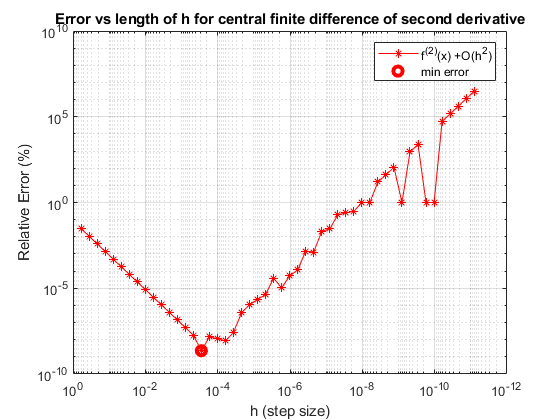



figure;
loglog(hs,error(2,:),'r-*')
hold on;
[minV,idx] = min(error(2,:));
loglog(hs(idx),error(2,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
xlabel("h (step size)")
ylabel("Relative Error (%)")
grid
title("Error vs length of h for central finite difference of second derivative")
legend("f^{(2)}(x) +O(h^2)","min error")
hold off

## Diferencia finita hacia adelante 

Similarmente a como despejamos la primera y segunda derivada de un sistema de ecuaciones de series de Taylor, podemos despejarlas de manera que sólo usemos puntos adelante de $x$, es decir, puntos de la forma $x+\left(n\right)h$ para $n\ge 0$.

### Primer derivada finita hacia adelante

$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x\right)}{h}+$$$ \mathcal{O}(h)$$                                             (a)

$f^{\prime } \left(x\right)\approx \frac{-\frac{1}{2}\;f\left(x+2h\right)+2f\left(x+h\right)-\frac{3}{2}f\left(x\right)}{h}+$$$ \mathcal{O}(h^2)$$             (b)

La ecuación (a) y (b) aproximan la primera derivada de $f\left(x\right)$, sin embargo (b) lo hace con mayor precisión, pues el error de truncamiento es de orden 2, y como $h\le 1\;$, el error se minimiza.

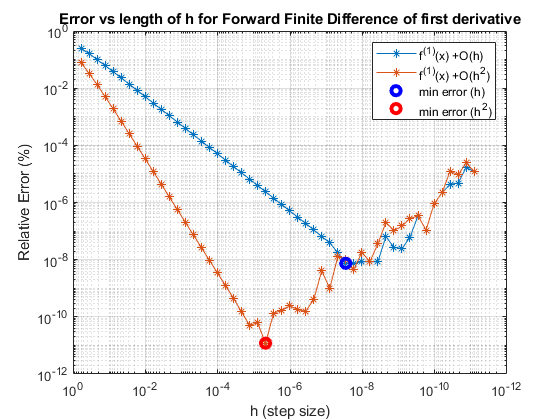


figure;
loglog(hs,error(3:4,:),"-*")
hold on
[minV,idx] = min(error(3,:));
loglog(hs(idx),error(3,idx),"b o",'MarkerSize',7,'LineWidth',3)
[minV,idx] = min(error(4,:));
loglog(hs(idx),error(4,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
grid
xlabel("h (step size)")
ylabel("Relative Error (%)")
title("Error vs length of h for Forward Finite Difference of first derivative")
legend("f^{(1)}(x) +O(h)","f^{(1)}(x) +O(h^2)","min error (h)","min error (h^2)")
hold off

### Segunda derivada finita hacia adelante

${f^{\prime } }^{\prime } \left(x\right)\approx \;\frac{f\left(x+2h\right)-2f\left(x+h\right)+f\left(x\right)}{h^2 }+$$$ \mathcal{O}(h)$$                                                  (a)

${f^{\prime } }^{\prime } \left(x\right)\approx \;\frac{-f\left(x+3h\right)+4f\left(x+2h\right)-5f\left(x+h\right)+2f\left(x\right)}{h^2 }+$$$ \mathcal{O}(h^2)$$                        (b)

Al igual que con la primera derivada finita hacia adelante, la ecuación (b) aproxima a la segunda con mayor presición que la ecuación (a).

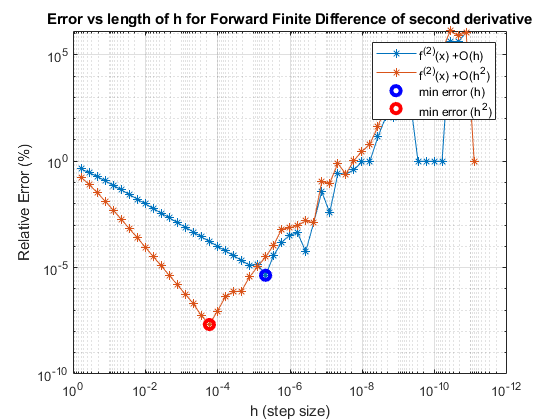

figure;
loglog(hs,error(5:6,:),"-*")
hold on
[minV,idx] = min(error(5,:));
loglog(hs(idx),error(5,idx),"b o",'MarkerSize',7,'LineWidth',3)
[minV,idx] = min(error(6,:));
loglog(hs(idx),error(6,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
xlabel("h (step size)")
ylabel("Relative Error (%)")
title("Error vs length of h for Forward Finite Difference of second derivative")
legend("f^{(2)}(x) +O(h)","f^{(2)}(x) +O(h^2)","min error (h)","min error (h^2)")
grid
hold off

## Diferencia finita hacia atrás

Para la diferencia finita hacia atrás usamos la función valuada en $x$ y $x-h$, es decir, en lugar de los valores de $x$ y $x+h$ tenemos: $f\left(x\right)-f\left(x-h\right)$.

### Primera derivada finita hacia atrás

A continuación hay dos fórmulas para la primera derivada hacia atrás. La segunda (b) es más precisa pues para su elaboración se incorporan más términos de la serie de Taylor. 

$f^{\prime } \left(x\right)=\;\frac{f\left(x\right)-f\left(x-h\right)}{h}+$$$ \mathcal{O}(h)$$                                              (a)

$f^{\prime } \left(x\right)=\frac{3f\left(x\right)-4f\left(x-h\right)+f\left(x-2h\right)}{2h}+$$$ \mathcal{O}(h^2)$$                      (b)

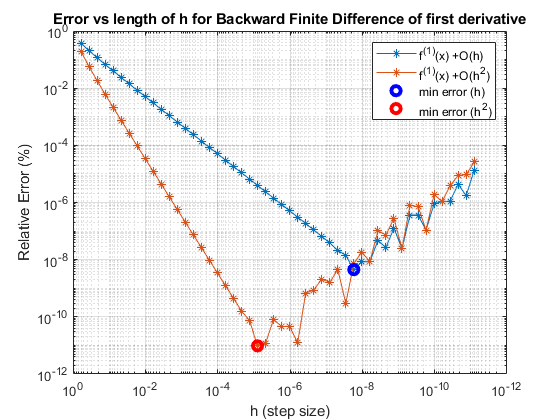

figure;
loglog(hs,error(7:8,:),"-*")
hold on
[minV,idx] = min(error(7,:));
loglog(hs(idx),error(7,idx),"b o",'MarkerSize',7,'LineWidth',3)
[minV,idx] = min(error(8,:));
loglog(hs(idx),error(8,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
grid
xlabel("h (step size)")
ylabel("Relative Error (%)")
title("Error vs length of h for Backward Finite Difference of first derivative")
legend("f^{(1)}(x) +O(h)","f^{(1)}(x) +O(h^2)","min error (h)","min error (h^2)")
hold off

#### Segunda derivada finita hacia atrás 

De la misma manera que para la primer derivada finita hacia atrás, la segunda fórmula (b) es más precisa que la primera (a).

${f^{\prime } }^{\prime } \left(x\right)=\frac{f\left(x\right)-2f\left(x-h\right)+f\left(x-2h\right)}{h^2 }+$$$ \mathcal{O}(h)$$                                         (a)

${f^{\prime } }^{\prime } \left(x\right)=\frac{2f\left(x\right)-5f\left(x-h\right)+4f\left(x-2h\right)-f\left(x-3h\right)}{\;h^2 }+$$$ \mathcal{O}(h^2)$$                (b)

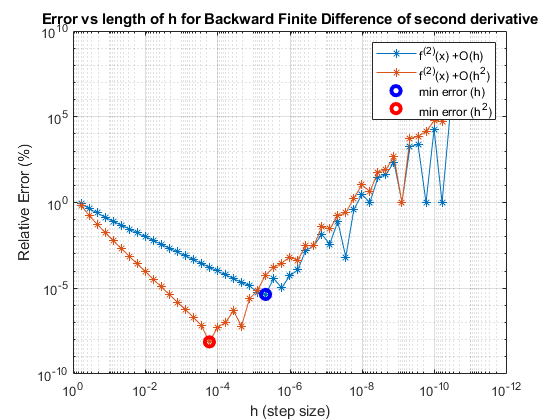


figure;
loglog(hs,error(9:10,:),"-*")
hold on
[minV,idx] = min(error(9,:));
loglog(hs(idx),error(9,idx),"b o",'MarkerSize',7,'LineWidth',3)
[minV,idx] = min(error(10,:));
loglog(hs(idx),error(10,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
grid
xlabel("h (step size)")
ylabel("Relative Error (%)")
title("Error vs length of h for Backward Finite Difference of second derivative")
legend("f^{(2)}(x) +O(h)","f^{(2)}(x) +O(h^2)","min error (h)","min error (h^2)")
hold off

## m-th derivative with precision n 

n=4;m=2;
n_coefs=2*floor((m+1)/2)-1+n; p=(n_coefs-1)/2;
% Solve system A*w = b
A=power(-p:p,(0:2*p)'); b=zeros(2*p+1,1); b(m+1)=factorial(m); coefs=A\b %inv(A)*b

coefs =   -0.083333333333333
   1.333333333333333
  -2.500000000000000
   1.333333333333333
  -0.083333333333333



% Round elements near values close to machine-epsilon to zero
coefs = coefs.*not(abs(coefs)<2000*eps);
format rational;
coefs

coefs =       -1/12    
       4/3     
      -5/2     
       4/3     
      -1/12    
